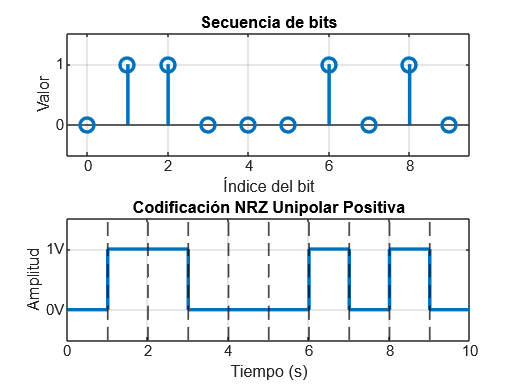

% ---------------------------------------------------------------
% Representación gráfica de la codificación NRZ Unipolar Positiva
% ---------------------------------------------------------------
% Este código genera una secuencia aleatoria de bits y grafica su representación
% en dos subgráficos: 
% 1. La secuencia de bits en un diagrama de pulsos.
% 2. La señal codificada en formato NRZ Unipolar Positiva.
% La codificación NRZ Unipolar Positiva asigna:
%   - Bit 1 → Nivel alto (1V)
%   - Bit 0 → Nivel bajo (0V)
% Se utiliza la función subplot para visualizar ambos gráficos en una misma figura.

clc;  % Limpia la ventana de comandos
clear;  % Borra todas las variables del espacio de trabajo
close all;  % Cierra todas las figuras abiertas

% --------------------------
% 1. Generación de la data
% --------------------------

% Secuencia aleatoria de bits (10 bits)
bit_seq = randi([0 1], 1, 10);

% Duración de cada bit en segundos
bit_duracion = 1;

% Frecuencia de muestreo (puntos por segundo)
fs = 100;  

% Definimos el eje de tiempo para la señal
t = 0:1/fs:length(bit_seq)*bit_duracion;  

% Inicializamos la señal en ceros
signal = zeros(size(t));

% -------------------------------
% 2. Construcción de la señal NRZ
% -------------------------------

index = 1;  % Índice inicial en el tiempo
for i = 1:length(bit_seq)
    if bit_seq(i) == 1
        signal(index:index+fs-1) = 1;  % Nivel alto para bit 1
    else
        signal(index:index+fs-1) = 0;  % Nivel bajo para bit 0
    end
    index = index + fs;  % Avanzar al siguiente bit
end

% -------------------------
% 3. Creación de la figura
% -------------------------

figure;  % Crear una nueva figura

% -------------------------------
% Subplot 1: Representación de bits
% -------------------------------
subplot(2,1,1); 
stem(0:length(bit_seq)-1, bit_seq, 'LineWidth', 2, 'MarkerSize', 8); 
ylim([-0.5 1.5]); 
xlim([-0.5 length(bit_seq)-0.5]);  
yticks([0 1]); 
yticklabels({'0', '1'}); 
xlabel('Índice del bit'); 
ylabel('Valor');  
title('Secuencia de bits');  
grid on; 

% -------------------------------
% Subplot 2: Señal NRZ Unipolar Positiva
% -------------------------------
subplot(2,1,2);  
stairs(t, signal, 'LineWidth', 2);
ylim([-0.5 1.5]); 
xlim([0 length(bit_seq)*bit_duracion]);  
yticks([0 1]); 
yticklabels({'0V', '1V'});  
xlabel('Tiempo (s)'); 
ylabel('Amplitud');  
title('Codificación NRZ Unipolar Positiva');
grid on; 
hold on;  

% Líneas verticales para separar los bits en la señal codificada
for i = 1:length(bit_seq)-1
    xline(i*bit_duracion, '--k', 'LineWidth', 1);  % Línea punteada negra
end

hold off;  % Desactivar retención de gráficos